# This code evaluates the test set.

% ** Important.  This script requires that:
% 1)'centroid_labels' be established in the workspace
% AND
% 2)'centroids' be established in the workspace
% AND
% 3)'test' be established in the workspace


% IMPORTANT!!:
% You should save 1) and 2) in a file named 'classifierdata.mat' as part of
% your submission.
load('classifierdata.mat','centroids','centroid_labels')
colormap('gray');
predictions = zeros(200,1);
outliers = zeros(200,1);

% loop through the test set, figure out the predicted number
for i = 1:200

    testing_vector=test(i,:);

    % Extract the centroid that is closest to the test image
    [prediction_index, vec_distance]=assign_vector_to_centroid(testing_vector,centroids);

    predictions(i) = centroid_labels(prediction_index);

end
cat(2,(1:200)',predictions);


## DESIGN AND IMPLEMENT A STRATEGY TO SET THE outliers VECTOR

outliers(i) should be set to 1 if the i^th entry is an outlier otherwise, outliers(i) should be 0

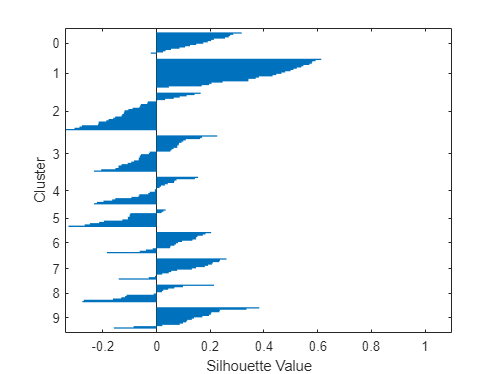

% Outliers with Silhouette
silhouette(test(:,1:784),predictions(:,size(predictions,2)));

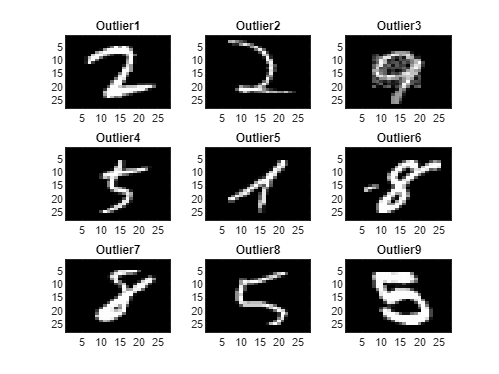

sil = silhouette(test(:,1:784),predictions(:,size(predictions,2)));
negativeInd = find(sil<0);
negativeSil = sil(sil<0);
quantile(negativeSil,0.25);
outliers = sil<(quantile(negativeSil,0.25)-.5*(abs(quantile(negativeSil,0.25))-abs(quantile(negativeSil,0.75))));
k=find(outliers);

plotsize=ceil(sqrt(size(k,1)));
for ind=1:size(k)
    centr=test(k(ind),[1:784]);
    subplot(plotsize,plotsize,ind);
    imagesc(reshape(centr,[28 28])');
    title(strcat('Outlier ',num2str(ind)))
end

## MAKE A STEM PLOT OF THE OUTLIER FLAG

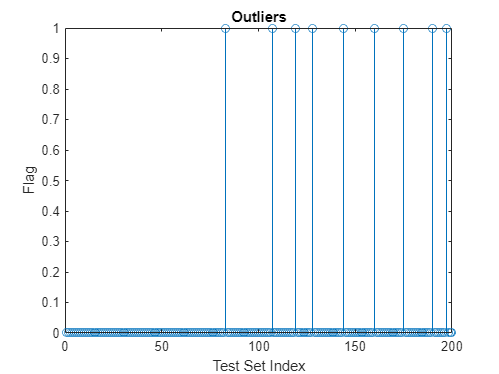

figure;
stem(1:size(test,1),outliers)
xlabel("Test Set Index")
ylabel("Flag")
title("Outliers")

## The following plots the correct and incorrect predictions

Make sure you understand how this plot is constructed

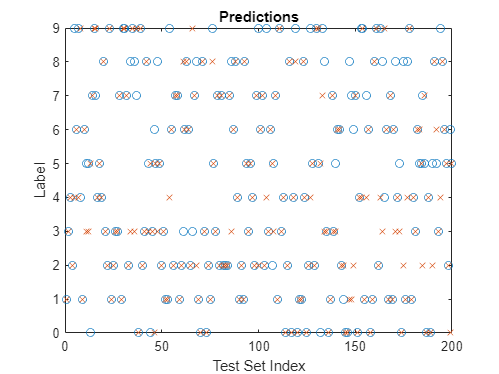

figure;
plot(correctlabels,'o');
hold on;
plot(predictions,'x');
title('Predictions');
xlabel("Test Set Index")
ylabel("Label")

## The following line provides the number of instances where and entry in correctlabel is

equatl to the corresponding entry in prediction However, remember that some of these are outliers

sum(correctlabels==predictions)

ans = 149

function [index, vec_distance] = assign_vector_to_centroid(data,centroids)
minC = 1;
dists = zeros([size(centroids,1),1]);
for c=1:size(centroids,1)
    dists(c) = norm(data(1:784)-centroids(c,1:784));
    if(dists(minC)>dists(c))
        minC = c;
    end
end
index = minC;
vec_distance = dists(minC);
end